# Resolver ecuaciones diferenciales

## dsolve

Función de Matlab encargada de resolver ecuaciones diferenciales

## **Ejemplo 1 **

Resovler la ecuación logística $\frac{dN}{dt}= rN\left(1-\frac{N}{K}\right)$

syms N(t) r K
eqn = diff(N,t) == r*N*(1-N/K);     %Definición de ecuación diferencial
S = dsolve(eqn)                     %solución analítica de ecuación diferencial

$$S = \left(\begin{array}{c} \frac{K}{{\mathrm{e}}^{C_{1}-r\,t}+1}\\ 0\\ K \end{array}\right)$$

Se puede trabajar con el problema de valor inicial a través de definir una serie de casos :$N(0)=4,\,N(0)=20,\,N(0)=0$

syms y(t) eq
eqn = diff(N,t) == 0.5*N*(1-N/20);
CI1 = N(0) == 4;        %Escenario 1
S1 = dsolve(eqn,CI1)

$$S1 = \frac{20}{{\mathrm{e}}^{\log\left(4\right)-\frac{t}{2}}+1}$$

CI2 = N(0) == 20;       %Escenario 2
S2 = dsolve(eqn,CI2)

$$S2 = 20$$

CI3 = N(0) == 0;        %Escenario 3
S3 = dsolve(eqn,CI3)

$$S3 = 0$$

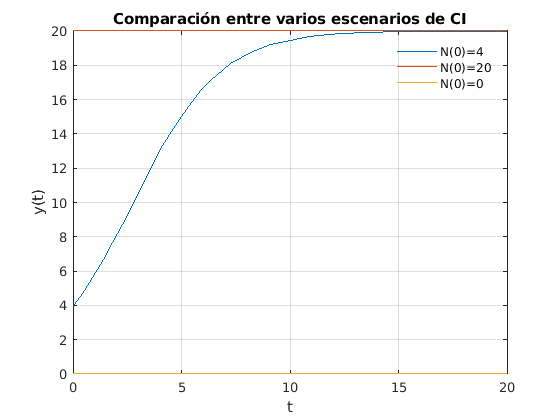

figure
fplot(S1,[0 20])
hold on
fplot(S2,[0 20])
fplot(S3,[0 20])
ylabel('y(t)')
xlabel('t')
grid on
legend({'N(0)=4', 'N(0)=20', 'N(0)=0'},"Box","off")
title("Comparación entre varios escenarios de CI")

## Ejemplo 2

Solucionar  $\frac{dy}{dt} = \frac{-t}{y}$

syms y(t); ecu = diff(y,t) == -t/y, dsolve(ecu)

$$ecu(t) = \frac{\partial }{\partial t}y\left(t\right)=-\frac{t}{y\left(t\right)}$$

$$ans = \left(\begin{array}{c} \sqrt{C_{1}-t^{2}}\\ -\sqrt{C_{1}-t^{2}} \end{array}\right)$$

Agregar condiciones iniciales $y(0)=2$

syms y(t); ecu = diff(y,t) == -t/y; ci = y(0) == 2; sol = dsolve(ecu,ci)

$$sol = \sqrt{4-t^{2}}$$

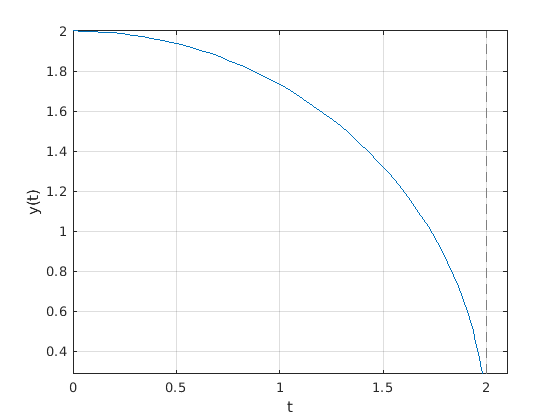

figure 
fplot(sol, [0 2.1])
grid on
ylabel('y(t)')
xlabel('t')

## Ejemplo 3

Solucionar la ecuación $(2t^2-y^2)dt+tydy =0$

En primer lugar, se debe llevar la expresión a la forma $\frac{dy}{dt}$.

En este caso sería: $\frac{dy}{dt}=-\frac{2}{y(t)/t} + \frac{y(t)}{t}$

Ahora podemos resolver la ecuación como en ejemplos anteriores:

syms y(t)
CI = y(2)==1;
equation = diff(y,t) == -2/(y/t) + y/t, dsolve(equation), SOL = dsolve(equation,CI)

$$equation(t) = \frac{\partial }{\partial t}y\left(t\right)=\frac{y\left(t\right)}{t}-\frac{2\,t}{y\left(t\right)}$$

$$ans = \left(\begin{array}{c} \sqrt{2}\,t\,\sqrt{C_{1}-2\,\log\left(t\right)}\\ -\sqrt{2}\,t\,\sqrt{C_{1}-2\,\log\left(t\right)} \end{array}\right)$$

$$SOL = \sqrt{2}\,t\,\sqrt{2\,\log\left(2\right)-2\,\log\left(t\right)+\frac{1}{8}}$$

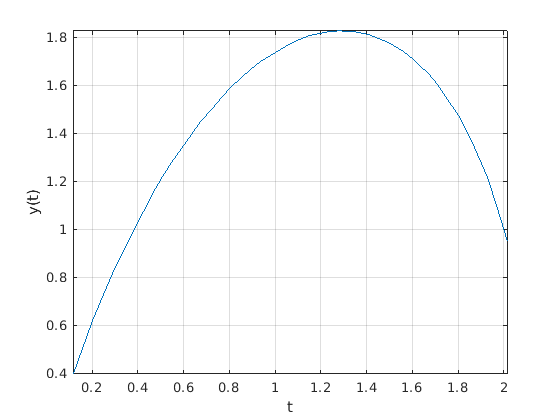

fplot(SOL)
grid on
ylabel('y(t)')
xlabel('t')

## Ejemplo 4

Solucionar ecuación de orden superior $\ddot{y} + 0.2\dot{y} + 0.5y=1$

syms y(t)
Dy = diff(y,t,1);                                   %Primera derivada
D2y = diff(y,t,2);                                  %Segunda derivada
ecu = D2y + 0.2*Dy + 0.5*y == 1;                    %Ecuación diferencial
ci1 = y(0) == 1; ci2 = Dy(0) == 2; ci = [ci1 ci2];  %Condiciones iniciales
sol = dsolve(ecu,ci)                                %Solución ecuación diferencial

$$sol = \frac{19\,\sin\left(\frac{7\,t}{10}\right)\,{\mathrm{e}}^{-\frac{t}{10}}}{7}-\cos\left(\frac{7\,t}{10}\right)\,{\mathrm{e}}^{-\frac{t}{10}}+2$$

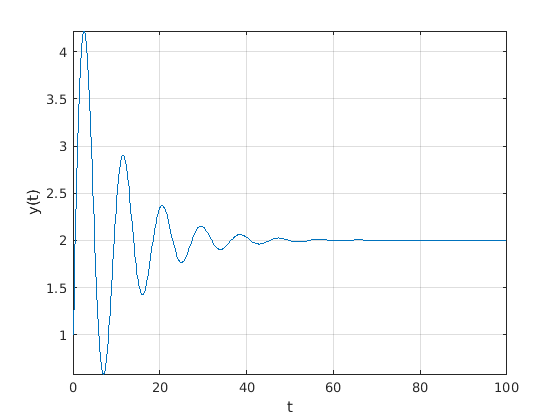

fplot(sol,[0,100])
grid on
ylabel('y(t)')
xlabel('t')

## Ejemplo 4

Solucionar ecuación de orden superior: $\dddot{y}+5\ddot{y}+6\dot{y}= \exp(-2t)$

syms y(t)
Dy = diff(y,t,1);         %Primera derivada
D2y = diff(y,t,2);        %Segunda derivada
D3y = diff(y,t,3);        %Tercera derivada
ecu = D3y + 5*D2y + 6*Dy == exp(-2*t)   %ecuación diferencial

$$ecu(t) = \frac{\partial^{3}}{\partial t^{3}}y\left(t\right)+5\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+6\,\frac{\partial }{\partial t}y\left(t\right)={\mathrm{e}}^{-2\,t}$$

ci1 = y(0) == 1; ci2 = Dy(0) == 0; ci3 = D2y(0) == -1; ci = [ci1 ci2 ci3]; %condiciones iniciales
sol = dsolve(ecu,ci)    %solución ecuación diferencial

$$sol = \frac{{\mathrm{e}}^{-3\,t}\,\left(11\,{\mathrm{e}}^{3\,t}+9\,{\mathrm{e}}^{t}-6\,t\,{\mathrm{e}}^{t}-8\right)}{12}$$

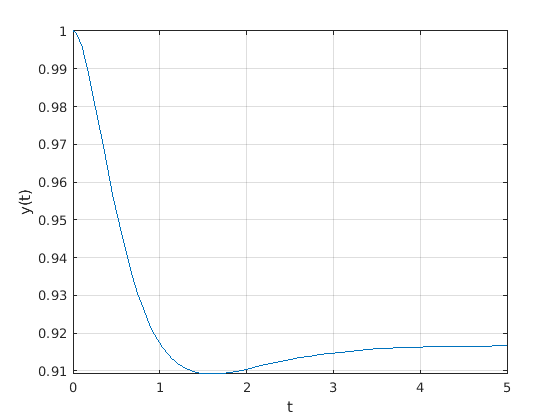

fplot(sol,[0,5])
grid on
ylabel('y(t)')
xlabel('t')